## 4.7. Mapping data between Python and MATLAB

In his book about [*Python for MATLAB Development*](https://link.springer.com/book/10.1007/978-1-4842-7223-7), Albert Danial shares some clever functions to convert MATLAB variables into an equivalent Python-native variable with [mat2py](https://github.com/Apress/python-for-matlab-development/blob/main/code/matlab_py/mat2py.m), and vice-versa with [py2mat](https://github.com/Apress/python-for-matlab-development/blob/main/code/matlab_py/py2mat.m).

[Converting data](https://www.mathworks.com/help/matlab/matlab_external/passing-data-to-python.html) returned by Python function inside of MATLAB may require understanding some of the differences in the native datatypes of the two languages:

- Scalars (integers, floating point numbers, …), text and Booleans

- Dictionaries and lists

- Arrays and dataframes

Some specialized MATLAB data types like *timetable* or *categorical* will require some extra love and need to be converted manually. Of course, we can still use these data types in our functions, but the functions need to return types that the Python interpreter can understand.

### 4.7.1. Scalars

The table below shows the mappings for common scalar data types:

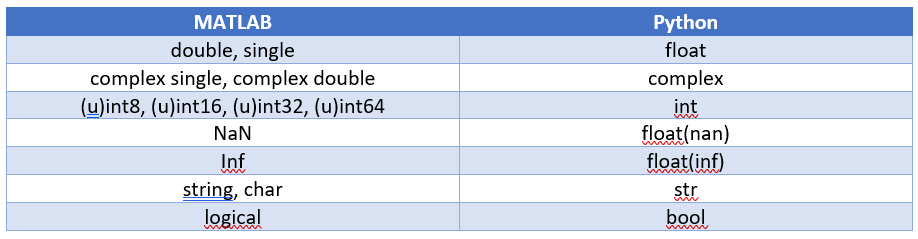

By default, numbers in MATLAB are double, whereas numbers without decimal point in Python are integers.

a = py.dataExchange.get_float()

a = 1

class(a)

ans = 'double'

b = py.dataExchange.get_complex()

b = 2.0000 + 0.0000i

class(b)

ans = 'double'

There are several kinds of integers in MATLAB, depending on the precision you require. 

For instance [uint8](https://www.mathworks.com/help/matlab/ref/uint8.html) can only store positive numbers between 0 and 255, whereas [int8](https://www.mathworks.com/help/matlab/ref/int8.html) covers the range [-2^7,2^7-1]

The most generic type to convert Python integers are int64, which you can do explicitely

c = py.dataExchange.get_integer()

c =   Python int with properties:

    denominator: [1×1 py.int]
           imag: [1×1 py.int]
      numerator: [1×1 py.int]
           real: [1×1 py.int]

    3


class(c)

ans = 'py.int'

int64(c)

ans = int64
3

When getting a string from a Python function, the convertion isn't obvious. It can either be turned into a [char](https://www.mathworks.com/help/matlab/ref/char.html) (character array) or a [string](https://www.mathworks.com/help/matlab/ref/string.html).

You can distinguish them by the single quotation marks for chars, and double quotes for strings.

abc = py.dataExchange.get_string()

abc =   Python str with no properties.

    abc


char(abc)

ans = 'abc'

class(char(abc))

ans = 'char'

string(abc)

ans = "abc"

class(string(abc))

ans = 'string'

Finally, the last basic datatype that contains a logical information is called a boolean in Python:

py.dataExchange.get_boolean()

ans = logical
   1


### 4.7.2. Dictionaries and Lists

This is how containers map to each other between the two languages:

To illustrate the conversion of Python dictionaries and lists into MATLAB containers, we will reuse the example from chapter 2.

JSON data are really close to dictionaries in Python, which makes the data processing very easy when accessing data from web services.

url = webread("https://samples.openweathermap.org").products.current_weather.samples{1};
r = py.urllib.request.urlopen(url).read();
json_data = py.json.loads(r);
py.weather.parse_current_json(json_data)

ans =   Python dict with no properties.

    {'temp': 280.32, 'pressure': 1012, 'humidity': 81, 'temp_min': 279.15, 'temp_max': 281.15, 'speed': 4.1, 'deg': 80, 'lon': -0.13, 'lat': 51.51, 'city': 'London', 'current_time': '2022-05-22 22:15:18.161296'}


Dictionaries can contain scalars, but also other datatypes like lists.

url2 = webread("https://samples.openweathermap.org").products.forecast_5days.samples{1};
r2 = py.urllib.request.urlopen(url2).read();
json_data2 = py.json.loads(r2);
forecast = struct(py.weather.parse_forecast_json(json_data2))

forecast = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×40 py.list]
             deg: [1×40 py.list]
           speed: [1×40 py.list]
        humidity: [1×40 py.list]
        pressure: [1×40 py.list]


forecastTemp = forecast.temp;
forecastTime = forecast.current_time;

Lists containing only numeric data can be converted into doubles since MATLAB R2022a:

double(forecastTemp)

ans =   261.4500  261.4100  261.7600  261.4600  260.9810  262.3080  263.7600  264.1820  264.6700  265.4360  266.1040  266.9040  268.1020  270.2690  270.5850  269.6610  269.1550  268.0560  265.8030  263.3810  261.8500  263.4550  264.0150  259.6840  255.1880  255.5940  256.9600  258.1090  259.5330  263.4380  264.2280  261.1530  258.8180  257.2180  255.7820  254.8190  257.4880  259.8270  261.2560  260.2600


And any lists can be converted to string (even those containing a mix of text and numeric data).

forecastTimeString = string(forecastTime);
datetime(forecastTimeString)

ans = 1×40 datetime array
   30-Jan-2017 18:00:00   30-Jan-2017 21:00:00   31-Jan-2017 00:00:00   31-Jan-2017 03:00:00   31-Jan-2017 06:00:00   31-Jan-2017 09:00:00   31-Jan-2017 12:00:00   31-Jan-2017 15:00:00   31-Jan-2017 18:00:00   31-Jan-2017 21:00:00   01-Feb-2017 00:00:00   01-Feb-2017 03:00:00   01-Feb-2017 06:00:00   01-Feb-2017 09:00:00   01-Feb-2017 12:00:00   01-Feb-2017 15:00:00   01-Feb-2017 18:00:00   01-Feb-2017 21:00:00   02-Feb-2017 00:00:00   02-Feb-2017 03:00:00   02-Feb-2017 06:00:00   02-Feb-2017 09:00:00   02-Feb-2017 12:00:00   02-Feb-2017 15:00:00   02-Feb-2017 18:00:00   02-Feb-2017 21:00:00   03-Feb-2017 00:00:00   03-Feb-2017 03:00:00   03-Feb-2017 06:00:00   03-Feb-2017 09:00:00   03-Feb-2017 12:00:00   03-Feb-2017 15:00:00   03-Feb-2017 18:00:00   03-Feb-2017 21:00:00   04-Feb-2017 00:00:00   04-Feb-2017 03:00:00   04-Feb-2017 06:00:00   04-Feb-2017 09:00:00   04-Feb-2017 12:00:00   04-Feb-2017 15:00:00


Before MATLAB R2022a, Python lists need to be converted into [MATLAB cell arrays](https://www.mathworks.com/help/matlab/cell-arrays.html).

Cells can then be transformed to double, strings, with the [cellfun](https://www.mathworks.com/help/matlab/ref/cellfun.html) function.

The previous code would look like this until R2021b:

forecastTempCell = cell(forecastTemp)

forecastTempCell = 1×40 cell array
    {[261.4500]}    {[261.4100]}    {[261.7600]}    {[261.4600]}    {[260.9810]}    {[262.3080]}    {[263.7600]}    {[264.1820]}    {[264.6700]}    {[265.4360]}    {[266.1040]}    {[266.9040]}    {[268.1020]}    {[270.2690]}    {[270.5850]}    {[269.6610]}    {[269.1550]}    {[268.0560]}    {[265.8030]}    {[263.3810]}    {[261.8500]}    {[263.4550]}    {[264.0150]}    {[259.6840]}    {[255.1880]}    {[255.5940]}    {[256.9600]}    {[258.1090]}    {[259.5330]}    {[263.4380]}    {[264.2280]}    {[261.1530]}    {[258.8180]}    {[257.2180]}    {[255.7820]}    {[254.8190]}    {[257.4880]}    {[259.8270]}    {[261.2560]}    {[260.2600]}


cellfun(@double,forecastTempCell)

ans =   261.4500  261.4100  261.7600  261.4600  260.9810  262.3080  263.7600  264.1820  264.6700  265.4360  266.1040  266.9040  268.1020  270.2690  270.5850  269.6610  269.1550  268.0560  265.8030  263.3810  261.8500  263.4550  264.0150  259.6840  255.1880  255.5940  256.9600  258.1090  259.5330  263.4380  264.2280  261.1530  258.8180  257.2180  255.7820  254.8190  257.4880  259.8270  261.2560  260.2600


forecastTimeCell = cell(forecastTime)

forecastTimeCell = 1×40 cell array
    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}    {1×19 py.str}


cellfun(@string,forecastTimeCell)

ans = 1×40 string array
    "2017-01-30 18:00:00"    "2017-01-30 21:00:00"    "2017-01-31 00:00:00"    "2017-01-31 03:00:00"    "2017-01-31 06:00:00"    "2017-01-31 09:00:00"    "2017-01-31 12:00:00"    "2017-01-31 15:00:00"    "2017-01-31 18:00:00"    "2017-01-31 21:00:00"    "2017-02-01 00:00:00"    "2017-02-01 03:00:00"    "2017-02-01 06:00:00"    "2017-02-01 09:00:00"    "2017-02-01 12:00:00"    "2017-02-01 15:00:00"    "2017-02-01 18:00:00"    "2017-02-01 21:00:00"    "2017-02-02 00:00:00"    "2017-02-02 03:00:00"    "2017-02-02 06:00:00"    "2017-02-02 09:00:00"    "2017-02-02 12:00:00"    "2017-02-02 15:00:00"    "2017-02-02 18:00:00"    "2017-02-02 21:00:00"    "2017-02-03 00:00:00"    "2017-02-03 03:00:00"    "2017-02-03 06:00:00"    "2017-02-03 09:00:00"    "2017-02-03 12:00:00"    "2017-02-03 15:00:00"    "2017-02-03 18:00:00"    "2017-02-03 21:00:00"    "2017-02-04 00:00:00"    "2017-02-04 03:00:00"    "2017-02-04 06:00:00"    "2017-02-04 09:00:00"    "2017-02-04 12:00:00" 

### 4.7.3. Arrrays

By modifying the parse_forecast_json function in the weather module, we can output [Python arrays](https://docs.python.org/3/library/array.html) instead of lists.

There exists indeed a native array datatype in base Python.

forecast2 = struct(py.weather.parse_forecast_json2(json_data2))

forecast2 = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×1 py.array.array]
             deg: [1×1 py.array.array]
           speed: [1×1 py.array.array]
        humidity: [1×1 py.array.array]
        pressure: [1×1 py.array.array]


The MATLAB double function will convert the Python array into a MATLAB array 

double(forecast2.temp)

ans =   261.4500  261.4100  261.7600  261.4600  260.9810  262.3080  263.7600  264.1820  264.6700  265.4360  266.1040  266.9040  268.1020  270.2690  270.5850  269.6610  269.1550  268.0560  265.8030  263.3810  261.8500  263.4550  264.0150  259.6840  255.1880  255.5940  256.9600  258.1090  259.5330  263.4380  264.2280  261.1530  258.8180  257.2180  255.7820  254.8190  257.4880  259.8270  261.2560  260.2600


Those data conversion also apply to Numpy arrays:

npA = py.numpy.array([1,2,3;4,5,6;7,8,9])

npA =   Python ndarray:

     1     2     3
     4     5     6
     7     8     9

    Use details function to view the properties of the Python object.

    Use double function to convert to a MATLAB array.


double(npA)

ans =      1     2     3
     4     5     6
     7     8     9


### 4.7.4. Dataframes

One common question on data transfer, is how to exchange data between MATLAB tables and Pandas Dataframes. The recommended solution for that is to rely on [Parquet files](https://www.mathworks.com/help/matlab/parquet-files.html). Parquet is a columnar storage format that enables to store & transfer tabular data between languages. It is available to any project in the Hadoop big data ecosystem, regardless of the choice of data processing framework, data model or programming language (more on [Parquet](https://parquet.apache.org/)).

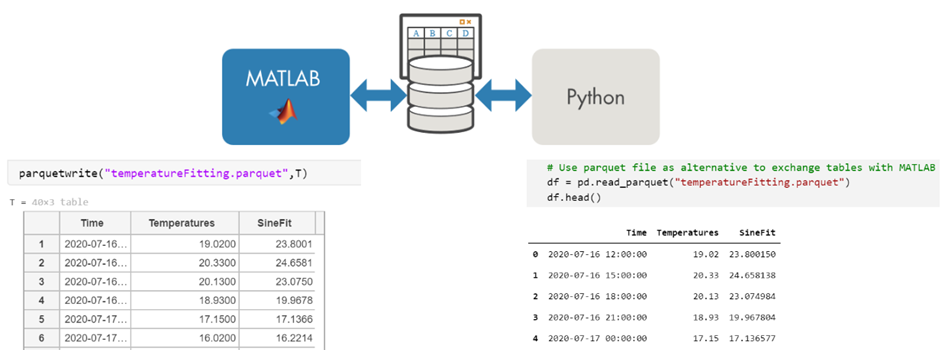

This example demonstrates a back and forth between Pandas DataFrames and MATLAB Tables:

**pq_CreateDataFrame.py**

Read in parquet file

% info = parquetinfo('data.parquet')
data = parquetread('data.parquet')

data = 3×3 table
    column1    column2    column3
    _______    _______    _______

       -1      "foo"       true  
      NaN      "bar"       false 
      2.5      "tree"      true  


Examine datatype of a particular column

class(data.column2)

ans = 'string'

Change data in table

data.column2 = ["orange"; "apple"; "banana"];

Write the results back to parquet

parquetwrite('newdata.parquet', data)

Finally read the modified DataFrame back in Python:

**pq_ReadTable.py**